# HW4

## q1

syms x1 x2

x = [x1;x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

v = x1^4 - x1^2*x2 + x2^2

$$v = {x_{1}}^{4}-{x_{1}}^{2}\,x_{2}+{x_{2}}^{2}$$


Dv = jacobian(v,x)

$$Dv = \left(\begin{array}{cc} 4\,{x_{1}}^{3}-2\,x_{1}\,x_{2} & 2\,x_{2}-{x_{1}}^{2} \end{array}\right)$$

D2v = jacobian(Dv,x)

$$D2v = \left(\begin{array}{cc} 12\,{x_{1}}^{2}-2\,x_{2} & -2\,x_{1}\\ -2\,x_{1} & 2 \end{array}\right)$$

det(D2v)

$$ans = 20\,{x_{1}}^{2}-4\,x_{2}$$

## q4

sys = @(t,x,k) [x(2); x(1)-x(1)^3 - k(1)*x(1)-k(2)*x(2)];
% close-loop 1
x0_1 = [1,1];
t_vec = linspace(0,10,1e6);
k1 = [2,2];
[t,x1] = ode45(@(t,x)sys(t,x,k1), t_vec, x0_1);

% close-loop 2
x0_2 = [-1,-1];
t_vec = linspace(0,10,1e6);
k2 = [2,2];
[t,x2] = ode45(@(t,x)sys(t,x,k2), t_vec, x0_2);

% close-loop 3
x0_3 = [-1,1];
t_vec = linspace(0,10,1e6);
k3 = [2,2];
[t,x3] = ode45(@(t,x)sys(t,x,k3), t_vec, x0_3);


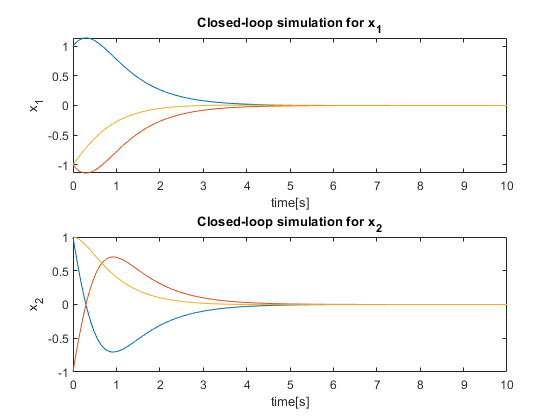

figure
subplot(2,1,1)
plot(t,x1(:,1))
hold on
plot(t,x2(:,1))
plot(t,x3(:,1))
title('Closed-loop simulation for x_1')
xlabel('time[s]')
ylabel('x_1')

subplot(2,1,2)
plot(t,x1(:,2))
hold on
plot(t,x2(:,2))
plot(t,x3(:,2))
title('Closed-loop simulation for x_2')
xlabel('time[s]')
ylabel('x_2')

% open-loop 1
x0_1 = [1,1];
t_vec = linspace(0,10,1e6);
k1 = [0 0];
[t,x1] = ode45(@(t,x)sys(t,x,k1), t_vec, x0_1);

% open-loop 2
x0_2 = [-1,-1];
t_vec = linspace(0,10,1e6);
k2 = [0 0];
[t,x2] = ode45(@(t,x)sys(t,x,k2), t_vec, x0_2);

% open-loop 3
x0_3 = [-1,1];
t_vec = linspace(0,10,1e6);
k3 = [0 0];
[t,x3] = ode45(@(t,x)sys(t,x,k3), t_vec, x0_3);

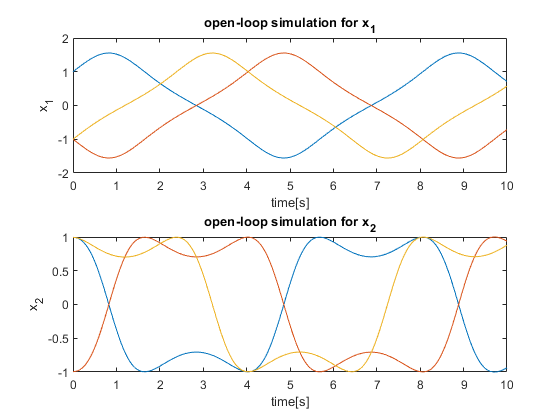

figure
subplot(2,1,1)
plot(t,x1(:,1))
hold on
plot(t,x2(:,1))
plot(t,x3(:,1))
title('open-loop simulation for x_1')
xlabel('time[s]')
ylabel('x_1')

subplot(2,1,2)
plot(t,x1(:,2))
hold on
plot(t,x2(:,2))
plot(t,x3(:,2))
title('open-loop simulation for x_2')
xlabel('time[s]')
ylabel('x_2')

## q5

syms x1 x2 
v = x1 - x1^3 + x1^4 - x2^2 + x2^4

$$v = {x_{1}}^{4}-{x_{1}}^{3}+x_{1}+{x_{2}}^{4}-{x_{2}}^{2}$$

x = [x1;x2];
dv = jacobian(v,x)

$$dv = \left(\begin{array}{cc} 4\,{x_{1}}^{3}-3\,{x_{1}}^{2}+1 & 4\,{x_{2}}^{3}-2\,x_{2} \end{array}\right)$$

d2v = jacobian(dv,x)

$$d2v = \left(\begin{array}{cc} 12\,{x_{1}}^{2}-6\,x_{1} & 0\\ 0 & 12\,{x_{2}}^{2}-2 \end{array}\right)$$


eig([-6*x1 0;0 -2])

$$ans = \left(\begin{array}{c} -2\\ -6\,x_{1} \end{array}\right)$$

## q6

syms x1 x2 lambda c
x = [x1;x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

xd = [x2;x1-x1^3-c*x2+1]

$$xd = \left(\begin{array}{c} x_{2}\\ -{x_{1}}^{3}+x_{1}-c\,x_{2}+1 \end{array}\right)$$

P = 1/2*[lambda*c^2 lambda*c;lambda*c 1];
v = x.'*P*x-1/2*x1^2+1/4*x1^4

$$v = x_{2}\,\left(\frac{x_{2}}{2}+\frac{c\,\lambda \,x_{1}}{2}\right)-\frac{{x_{1}}^{2}}{2}+\frac{{x_{1}}^{4}}{4}+x_{1}\,\left(\frac{\lambda \,x_{1}\,c^{2}}{2}+\frac{\lambda \,x_{2}\,c}{2}\right)$$

v = simplify(v)

$$v = \frac{\lambda \,c^{2}\,{x_{1}}^{2}}{2}+\lambda \,c\,x_{1}\,x_{2}+\frac{{x_{1}}^{4}}{4}-\frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}$$

dv = jacobian(v,x)

$$dv = \left(\begin{array}{cc} \lambda \,c^{2}\,x_{1}+\lambda \,x_{2}\,c+{x_{1}}^{3}-x_{1} & x_{2}+c\,\lambda \,x_{1} \end{array}\right)$$

dvf = dv*xd

$$dvf = \left(x_{2}+c\,\lambda \,x_{1}\right)\,\left(-{x_{1}}^{3}+x_{1}-c\,x_{2}+1\right)+x_{2}\,\left(\lambda \,c^{2}\,x_{1}+\lambda \,x_{2}\,c+{x_{1}}^{3}-x_{1}\right)$$


dvf = 2*x.'*P*xd  - x(1)*xd(1) + x(1)^3*xd(1)

$$ans = \left(x_{2}+c\,\lambda \,x_{1}\right)\,\left(-{x_{1}}^{3}+x_{1}-c\,x_{2}+1\right)-x_{1}\,x_{2}+{x_{1}}^{3}\,x_{2}+x_{2}\,\left(\lambda \,x_{1}\,c^{2}+\lambda \,x_{2}\,c\right)$$